**Import Data Set**

This is the working data set which will be used by this script.

dataset = importfile('S&P500');


**Import Yahoo Answers Data Set**

testSet = importfileYahoo('^GSPC');

**Data Pre-processing**

heightA = height(dataset);
heightB = height(testSet);
disp("number of rows: " + heightA);

number of rows: 17160



errorCounter = 0;
if heightA ~= heightB
    errorCounter = 1;
end

Iterates througth both data sets and compares the data.

when errors are found they are recorded in the error counter

tf = ismissing(dataset);
ts = ismissing(testSet);
if tf ~= ts
    errorCounter = errorCounter + 1;
end 
disp(" error: " + errorCounter);

 error: 0


**Data Normalisation**

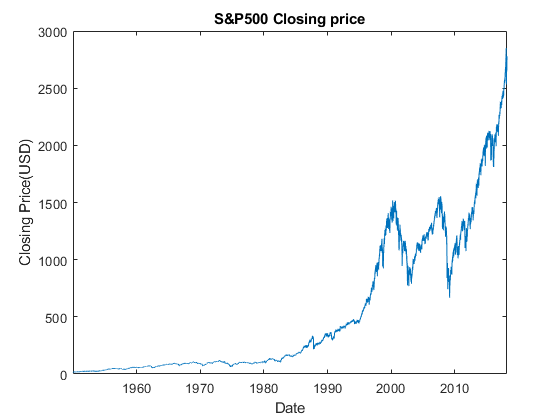

normalData = normalize(dataset{:,2:end});

sp500 = normalData(:,4);




figure;
date = dataset{:,1};
closingPrice = dataset{:,4};
plot(date,closingPrice);
title('S&P500 Closing price');
xlabel('Date');
ylabel('Closing Price(USD)');

Fit an ARIMA(1,1,1) model to the data. 

Mdl = arima(1,1,1);
EstMdl = estimate(Mdl,sp500);

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    7.2994e-05     2.8132e-05        2.5947        0.0094673
    AR{1}          0.70792       0.019428        36.439      1.0403e-290
    MA{1}         -0.75818        0.01789       -42.379                0
    Variance    0.00017475     5.7038e-07        306.37                0



Forecast the Composite Index for 500 days using the fitted model. Use the observed data as presample data. 

[Y,YMSE] = forecast(EstMdl,30,sp500);

Plot the forecasts and 95% forecast intervals. 

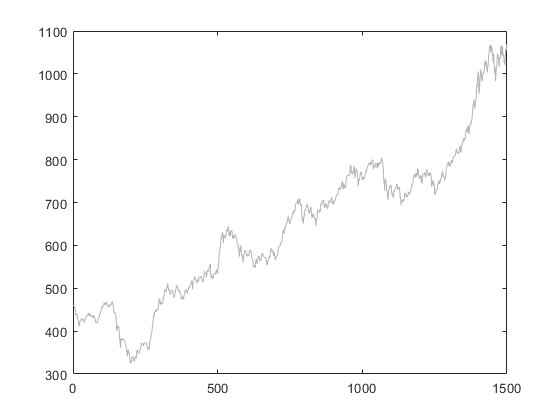

lower = Y - 1.96*sqrt(YMSE);
upper = Y + 1.96*sqrt(YMSE);

figure
plot(nasdaq,'Color',[.7,.7,.7]);
hold on

h1 = plot(1501:2000,lower,'r:','LineWidth',2);

Error using plot
Vectors must be the same length.

plot(1501:2000,upper,'r:','LineWidth',2)
h2 = plot(1501:2000,Y,'k','LineWidth',2);
legend([h1 h2],'95% Interval','Forecast',...
	     'Location','NorthWest')
title('NASDAQ Composite Index Forecast')
hold off

xlim([0 2000])
ylim([200 1600])